#  LocalizationHeatMap.mlx

% =================================================================

%  Copyright © 2023-2025 Xiaofeng Dai (xiaofend@umich.edu)

%  SPDX-License-Identifier: GPL-3.0-or-later

%

%  This program is free software: you can redistribute it and/or modify

%  it under the terms of the GNU General Public License as published by

%  the Free Software Foundation, either version 3 of the License, or

%  (at your option) any later version.

%

%  This program is distributed in the hope that it will be useful,

%  but WITHOUT ANY WARRANTY; without even the implied warranty of

%  MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the

%  GNU General Public License for more details.

%

%  You should have received a copy of the GNU General Public License

%  along with this program (LICENSE file in the repository root).

%  If not, see <https://www.gnu.org/licenses/>.

%

%  Tested with: MATLAB R2024a and R2022a

% =================================================================

### LOCALIZATION HEAT‑MAP WORKFLOW (LIVE SCRIPT)

% -------------------------------------------

% This live script performs three major tasks:

%   1. **Cell geometry extraction** — replicate the analysis in

%      *Cell_Morphology.mlx* to obtain long/short axes, aspect ratio and area.

%   2. **Cell morphology and localizaiton precision filtering** . Cell masks are 

%      from segmentation results by cellpose/omnipose; fits and track files are results

%      from trakcing analysis by SMALL-LABS.

%   3. **Heatmap** — plot 2‑D histograms (raw and fully

%      quadruply symmetrized) and save PNG outputs.

% -------------------------------------------------------------------------

### Select data directory & load files

%% Select data directory & load files
Filefolder=uigetdir('Example_Folder/subfolder');
Fitsname=uigetfile([Filefolder,filesep,'*fits.mat'],'MultiSelect','on');
Maskname=uigetfile([Filefolder,filesep,'*PhaseMask.mat'],'MultiSelect',"on");
Num_file=length(Fitsname);

Store_Mask=cell(Num_file,1);
Store_tracks=cell(Num_file,1);
Store_fits = cell(Num_file,1);

% Use parallel loading for speed (tracks + fits + masks)
parfor i=1:Num_file
    fitsname=Fitsname{i};
    fitspath=[Filefolder,filesep,fitsname];
    track = load(fitspath,'tracks');
    fits = load(fitspath,'fits');
    Store_fits{i} = fits.fits;
    Store_tracks{i} = track.tracks;
    maskname=Maskname{i};
    maskpath=[Filefolder,filesep,maskname];
    mask = load(maskpath);
    Store_Mask{i} = mask.PhaseMask;
end
% clear i fitsname fitspath track maskname maskpath mask

### Cell Morphology Distribution  (same as Cell_Morphology.mlx)

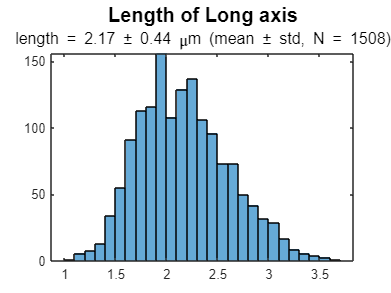

% set up pixel size before running!
pixel_size=49; % nm per pixel

num_roi=Num_file;
Result_Filter=cell(num_roi,1);
parfor i=1:num_roi
    mask=Store_Mask{i};
    num_cell=max(mask,[],"all");
    result=zeros(num_cell,5);
    result(:,1)=(1:1:num_cell);
    roi_size=size(mask);
    for j=1:num_cell
        singlecell=mask;
        singlecell(singlecell~=j)=0;
        [ind1, ind2]=find(singlecell==j);
        if isempty(ind1)
            continue
        end
        r_up=min(ind1);
        r_up=max(1,r_up-10);
        r_down=max(ind1);
        r_down=min(r_down+10,roi_size(1));
        col_left=min(ind2);
        col_left=max(1,col_left-10);
        col_right=max(ind2);
        col_right=min(roi_size(2),col_right+10);
        singlecell=singlecell(r_up:r_down,col_left:col_right);
        singlecell=singlecell/j;
        ImgProp = regionprops('table',singlecell,'PixelList');
        FeretAna = feretProperties(ImgProp);
        Longaxis=FeretAna.MaxFeretDiameter;
        Shortaxis=FeretAna.MinFeretDiameter;
        aspt_ratio=Longaxis/Shortaxis;
        result(j,2)=Longaxis*pixel_size/1000;            %length of long axis in um
        result(j,3)=Shortaxis*pixel_size/1000;           %length of short axis in nm
        result(j,4)=aspt_ratio;                          %aspect ratio
        result(j,5)=length(ind1)*(pixel_size^2)/1e6;     % size of each cell in um^2
    end
    Result_Filter{i}=result;
end

clear col_left col_right r_up r_down Longaxis
clear FeretAna i j ImgProp ind1 ind2 Lon Shortaxis aspt_ratio num_cell
clear result roi_size singlecell mask  num_roi


Result_cat=cat(1,Result_Filter{:});
Result_cat=Result_cat(Result_cat(:,2)~=0,:);


% ---- Diagnostic histograms (lengths, AR, area) ----
figure
str1 = { ['length = ' sprintf('%.2f ± %.2f', mean(Result_cat(:,2)), std(Result_cat(:,2))) ]};
str2 = {[' ' sprintf('(mean ± std, N = %d)', numel(Result_cat(:,2)))]};
str=append(str1,' \mu','m',str2);
histogram(Result_cat(:,2))
[t,s]=title('Length of Long axis',str);
t.FontSize=15;
s.FontSize=12;

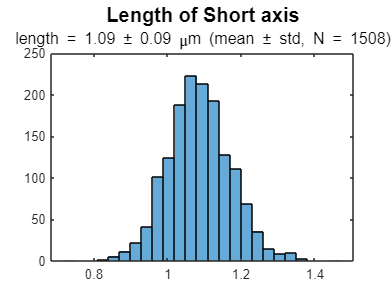


figure
% str = { [ 'length = ' sprintf('%.2f ± %.2f nm (mean ± std, N = %d)', mean(Result_cat(:,3)), std(Result_cat(:,3)), numel(Result_cat(:,3))) ] };
str1 = { ['length = ' sprintf('%.2f ± %.2f', mean(Result_cat(:,3)), std(Result_cat(:,3))) ]};
str2 = {[' ' sprintf('(mean ± std, N = %d)', numel(Result_cat(:,3)))]};
str=append(str1,' \mu','m',str2);
histogram(Result_cat(:,3))
[t,s]=title('Length of Short axis',str);
t.FontSize=15;
s.FontSize=12;

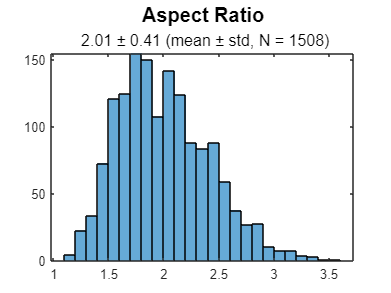


figure
% str = { [ ' ' sprintf('%.2f ± %.2f (mean ± std, N = %d)', mean(Result_cat(:,4)), std(Result_cat(:,4)), numel(Result_cat(:,4))) ] };
str1 = { [' ' sprintf('%.2f ± %.2f', mean(Result_cat(:,4)), std(Result_cat(:,4))) ]};
str2 = {[' ' sprintf('(mean ± std, N = %d)', numel(Result_cat(:,4)))]};
str=append(str1,str2);
histogram(Result_cat(:,4))
[t,s]=title('Aspect Ratio',str);
t.FontSize=15;
s.FontSize=12;

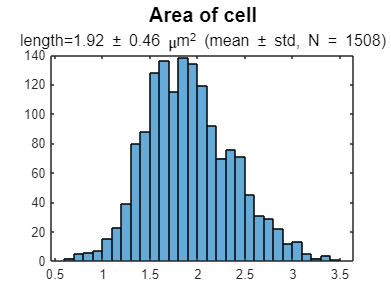


figure
% str = { [ 'Area = ' sprintf('%.2e ± %.2e nm^2 (mean ± std, N = %d)', mean(Result_cat(:,5)), std(Result_cat(:,5)), numel(Result_cat(:,5))) ] };
str1 = { ['length=' sprintf('%.2f ± %.2f', mean(Result_cat(:,5)), std(Result_cat(:,5))) ]};
str2 = {[' ' sprintf('(mean ± std, N = %d)', numel(Result_cat(:,5)))]};
str=append(str1,' {\mu}','m^2',str2);
histogram(Result_cat(:,5))
[t,s]=title('Area of cell',str);
s.FontSize=12;
t.FontSize=15;


clear s t str1 str2 str

### **Set up parameters for filtering and heatmap**

gap_y = 1/20;   % grid size (normalised y‑axis)
num_pix_y = 1/gap_y;    % number of bins along Y

% upper and lower bounds for cell geometry filter
low_bd = 1.5;
up_bd = 4;
% col 2 was used for cell length filter
% col 3 --> cell width; col 4 --> aspect ratio; col 5 --> cell area
rowstokeep = Result_cat(:,2)>=low_bd & Result_cat(:,2) <= up_bd;
Result_cat=Result_cat(rowstokeep,:);

aspt=Result_cat(:,4);
aspt_ratio = round(mean(aspt)*num_pix_y/2)*2/num_pix_y;

disp(['Mean aspect ratio = ' sprintf('%.2f', mean(aspt)) '    ~' sprintf('%.2f', aspt_ratio)])

Mean aspect ratio = 2.03    ~2.00


disp(['Number of grids y axis = ' sprintf('%.0f', num_pix_y) newline 'Number of grids x axis = ' sprintf('%.0f', round(mean(aspt)*num_pix_y/2)*2)])

Number of grids y axis = 20
Number of grids x axis = 40



Index = cell(Num_file,1);
for i=1:Num_file
    cell_len = Result_Filter{i};
    test1 = cell_len(:,2)<=up_bd;
    test2 = cell_len(:,2)>=low_bd;
    test = test1+test2;
    ind = test==2;
    index = cell_len(ind,1);
    Index{i}=index;
end
clear i cell_len test1 test2 test ind index

run this section if you want to force aspect ratio 

% force aspect ratio of heatmap
aspt_ratio = 2.1

aspt_ratio = 2.1000

### Calculate normalized coordinates for each localizaiton

loc_precision = 500; % nm, localizaiton precision
uncertainty = loc_precision/pixel_size;
Result_all=cell(Num_file,1);
for i=1:Num_file
    tracks = Store_tracks{i};
    goodfit = Store_fits{i}.goodfit;
    widthcCI  = Store_fits{i}.widthcCI;
    % localizaiton precision filter
    tracks_deter = zeros(height(tracks),1);
    for iter = 1:height(tracks)
        molid = tracks(iter,6);
        if goodfit(molid)==1 && widthcCI(molid)<uncertainty
            tracks_deter(iter) = 1;
        end
    end
    tracks = tracks(tracks_deter==1,:);


    PhaseMask = Store_Mask{i};
    index = Index{i};
    
    Numcell=length(index);
    MaskStore=cell(Numcell,1);
    if isempty(tracks)==0
        for iw=1:Numcell
            ind = index(iw);
            SingleCell=PhaseMask;
            SingleCell(SingleCell~=ind)=0;
            MaskStore{iw}=SingleCell;
            
        end
        TrackStore=cell(Numcell,1);
        for ia=1:Numcell
            ind = index(ia);
            loc_index=tracks(:,5)==ind;
            TrackStore{ia}=tracks(loc_index,2:3);
        end
    end
    
    % normalize localizaiton coordinate based on the lengths of 
    % cell long and short axises. 
    % the cell length and width is defined by the maximum and minimum 
    % feret diameters
    Result_Singlecell=cell(Numcell,1);
    try
        for ik=1:Numcell
            if isempty(TrackStore{ik})==0
                ImgProp = regionprops('table',MaskStore{ik},'PixelList');
                FeretAna = feretProperties(ImgProp);
                %%%
                test=FeretAna;
                deter=test.PixelList;
                buff=zeros(length(deter));
                for w=1:length(deter)
                    if isempty(deter{w})==0
                        buff(w)=1;
                    end
                end
                FeretAna=test(buff==1,:);
                clear test deter buff w 
                %%%
                PoleAxis = cell2mat(FeretAna.MaxFeretDiameterEndpoints); %FeretAna.MaxFeretDiameterEndpoints
                center = cell2mat(FeretAna.MinAreaBoundingBox);
                center = (center(1,:)+center(3,:))/2;
                Xlength = FeretAna.MaxFeretDiameter;
                if FeretAna.MaxFeretDiameterOrientation>0
                    PoleAngleX=180-FeretAna.MaxFeretDiameterOrientation;
                    PoleAngleX=(PoleAngleX*pi)/180;
                elseif FeretAna.MaxFeretDiameterOrientation<=0
                    PoleAngleX=-(pi*FeretAna.MaxFeretDiameterOrientation)/180;
                end
                Ylength=FeretAna.MinFeretDiameter;
                if FeretAna.MinFeretDiameterOrientation>0
                    PoleAngleY=180-FeretAna.MinFeretDiameterOrientation;
                    PoleAngleY=(PoleAngleY*pi)/180;
                elseif FeretAna.MinFeretDiameterOrientation<=0
                    PoleAngleY=-(pi*FeretAna.MinFeretDiameterOrientation)/180;
                end
                tmpstore=TrackStore{ik};
                tmp5=size(tmpstore);
                tmp5=tmp5(1);
                vecter=zeros(tmp5,8);
                % vecter col#1&col#2 vecter(x,y) connecting each point and center
                % vecter col#3 real distance between point and center
                % vecter col#4 angle between vecter(x,y) and xaxis (1,0)
                % vecter col#5 vecter(x,y) angle to PoleAngleX
                % vecter col#6 vecter(x,y) angle to PoleAngleY
                % vecter col#7&col#8 normalized coordinate
                vecter(:,1)=tmpstore(:,2)-center(1);
                vecter(:,2)=-tmpstore(:,1)+center(2);
                vecstd=[1,0];
            
                for ii=1:tmp5
                    vecter(ii,4)=anglevec(vecstd,[vecter(ii,1),vecter(ii,2)]);
                end
                clear ii
                vecter(:,3)=sqrt(vecter(:,1).^2+vecter(:,2).^2);
                for ii=1:tmp5
                    thetaX=PoleAngleX-vecter(ii,4);
                    if (thetaX<=-pi) && (thetaX>-2*pi)
                        vecter(ii,5)=mod(thetaX,pi);
                    else
                        vecter(ii,5)=thetaX;
                    end
                end
                clear ii
                for ii=1:tmp5
                    thetaY=PoleAngleY-vecter(ii,4);
                    if (thetaY<=-pi) && (thetaY>-2*pi)
                        vecter(ii,6)=mod(thetaY,pi);
                    else
                        vecter(ii,6)=thetaY;
                    end
                end
                clear ii
                angleref=abs(PoleAngleX-PoleAngleY);
                vecter(:,7)=(vecter(:,3)/sin(angleref)).*sin(vecter(:,6));
                vecter(:,8)=(vecter(:,3)/sin(angleref)).*sin(vecter(:,5));
                vecter(:,7)=vecter(:,7)/Xlength;
                vecter(:,8)=vecter(:,8)/Ylength;
                
                store=zeros(tmp5,3);
                store(:,1)=vecter(:,7);
                store(:,2)=vecter(:,8);
                Result_Singlecell{ik}=store;
            
            end
            
        end
    catch
    end
    clear store
    % Post‑processing: remove outliers (>0.5 normalized units)
    for il=1:Numcell
        tmp7=isempty(Result_Singlecell{il,1});
        if tmp7==0
            store=Result_Singlecell{il,1};
            len_all=size(store);
            len_all=len_all(1);
            indct1=find(abs(store(:,1))>0.5);
            len1=size(indct1);
            indct2=find(abs(store(:,2))>0.5);
            len2=size(indct2);
            len_err=len1+len2;
            len_err=len_err(1);
            if isempty(indct1) && isempty(indct2)
                Result_Singlecell{il,1}=store;
            elseif len_err<0.05*len_all
                indct=cat(1,indct1,indct2);
                clear index
                index=unique(indct);
                store(index,:)=[];
                Result_Singlecell{il,1}=store;
            elseif len_err>=0.05*len_all
                Result_Singlecell{il,1}=[];
            end
            
        end
        Result_File=cat(1,Result_Singlecell{:});
        Result_all{i}=Result_File;
    end
    
end

Estimate mean localization precision (optional )

a = cat(1,Store_fits{:});
b = struct2cell(a);
c = b(16,:);
c = cat(1,c{:});

c1 = c;
c1(c>uncertainty)=[];
fprintf('mean localizaiton precison = %.2f \n',nanmean(c1)*pixel_size)

mean localizaiton precison = 129.97 


clear a b c c1

### Concatenate coordinates from each cell and plot heat map

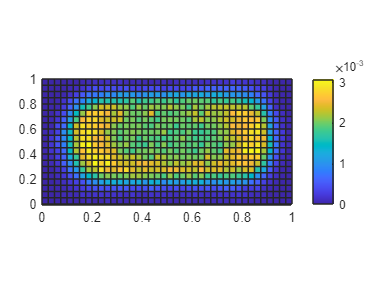

gap_x = gap_y/aspt_ratio;

Result_cat=cat(1,Result_all{:});
histogram2(Result_cat(:,1),Result_cat(:,2),'XBinEdges',-0.5:gap_x:0.5,'YBinEdges',-0.5:gap_y:0.5,...
    'Normalization','probability','DisplayStyle','tile','FaceColor','flat','ShowEmptyBins','on')
pbaspect([2 1 1])
colormap(gca,'parula');
colorbar;
xlim([-0.5 0.5])
xticks([-0.5  -0.3  -0.1  0.1  0.3  0.5])
ylim([-0.5 0.5])
yticks([-0.5  -0.3  -0.1  0.1  0.3  0.5])
xticklabels({'0','0.2','0.4','0.6','0.8','1'});
yticklabels({'0','0.2','0.4','0.6','0.8','1'})
pbaspect([aspt_ratio 1 1])

% set(gca,'CLim',[0,3e-3])
% save plot
mkdir([Filefolder,filesep,'Results'])

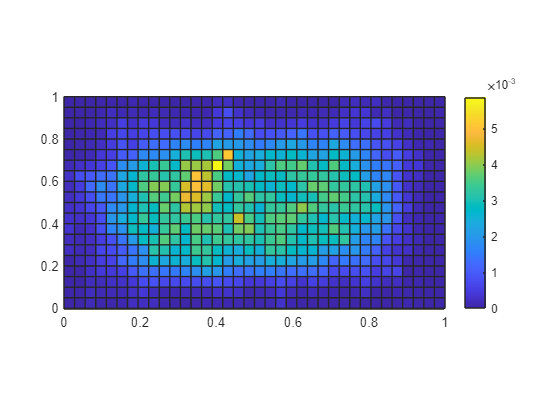

saveas(gcf,[Filefolder,filesep,'Results',filesep,'Localization_HeatMap_noSym.png'])

### Symmetrized heat map (4-fold, along long and short axises)

for i=1:size(Result_cat)
    if Result_cat(i,1)>0
        Result_cat(i,1)=-Result_cat(i,1);
    end
    if Result_cat(i,2)>0
        Result_cat(i,2)=-Result_cat(i,2);
    end
end
Result_cat3=[Result_cat(:,1) -Result_cat(:,2)];
Result_cat4=[-Result_cat(:,1) -Result_cat(:,2)];
Result_cat5=[-Result_cat(:,1) Result_cat(:,2)];
Result_cat_sym=[Result_cat(:,[1 2]);Result_cat3;Result_cat4;Result_cat5];

histogram2(Result_cat_sym(:,1),Result_cat_sym(:,2),'XBinEdges',-0.5:gap_x:0.5,'YBinEdges',-0.5:gap_y:0.5,...
    'Normalization','probability','DisplayStyle','tile','FaceColor','flat','ShowEmptyBins','on')
pbaspect([2 1 1])
colormap(gca,'parula');
colorbar;
xlim([-0.5 0.5])
xticks([-0.5  -0.3  -0.1  0.1  0.3  0.5])
ylim([-0.5 0.5])
yticks([-0.5  -0.3  -0.1  0.1  0.3  0.5])
xticklabels({'0','0.2','0.4','0.6','0.8','1'});
yticklabels({'0','0.2','0.4','0.6','0.8','1'})
pbaspect([aspt_ratio 1 1])
% title 'W3110 24H'
% set(gca,'CLim',[0,2e-3])

str1 = { [' ' sprintf('Lower bound = %.1f', low_bd) ]};
str2 = { [' ' sprintf('Upper bound =  %.1f', up_bd) ]};
str3 = { [' ' sprintf('Aspect ratio = %.2f', aspt_ratio) ]};
str=append(str1,'\mu','m',', ',str2,'\mu','m','. ',str3);
[t,s] = title('Localization Heat Map after filtering',str);

% % get the position of the title
titlePos = get( t , 'position');

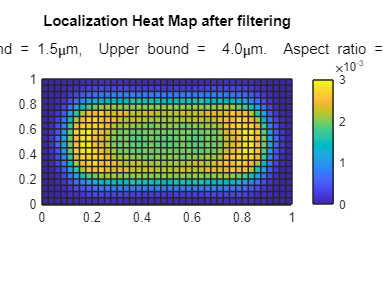

% change the x value  to 0
titlePos = titlePos + [0 0.27 0] ;
% update the position
set( t , 'position' , titlePos);

% % get the position of the title
titlePos = get( s , 'position');
% change the x value  to 0
titlePos = titlePos + [0 0.145 0] ;
% update the position
set( s , 'position' , titlePos);
set(gca,'CLim',[0,3e-3])


Num_cells = length(cat(1,Index{:})) % number of cell used for analysis

Num_cells = 1446

Num_loc = length(Result_cat)        % number of localizaitons

Num_loc = 177230

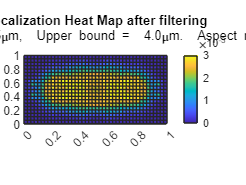


% save mat file and heatmap plot
mkdir([Filefolder,filesep,'Results'])
saveas(gcf,[Filefolder,filesep,'Results',filesep,'Localization_HeatMap_filtering.png'])

save(strcat(Filefolder,filesep,'Results',filesep,'Result_cat.mat'),'Result_cat')